# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

clc; clear;
robot_name = 'kinovaGen3';
% robot_name = "abbIrb120";
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

% endEffector = "EndEffector_Link";
endEffector = robot.BodyNames{end};

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([0.4 0 0.2])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

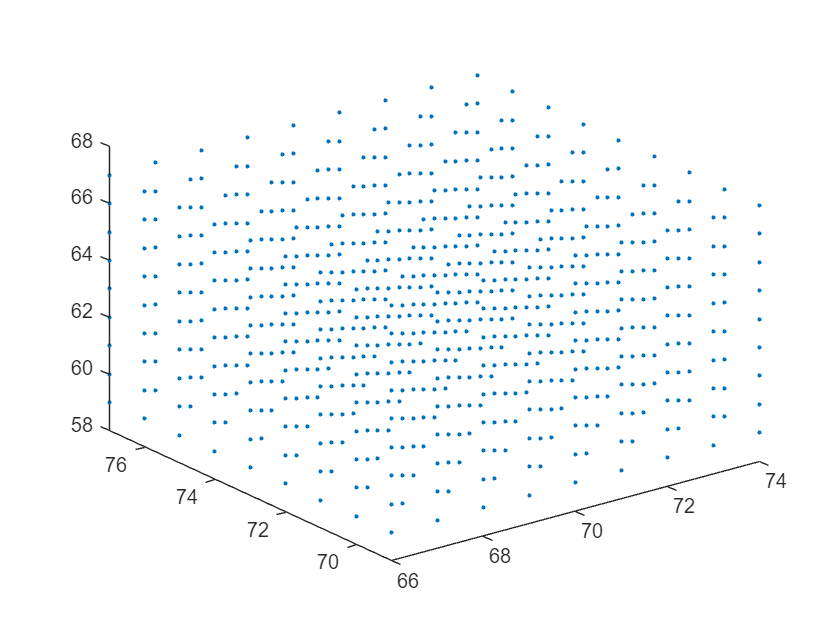

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

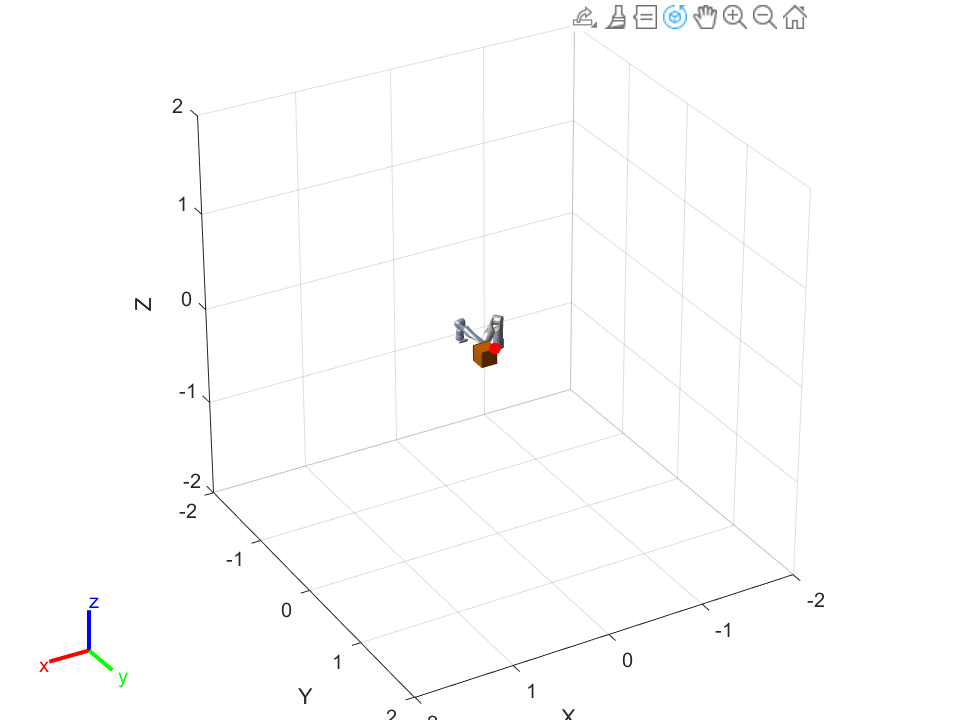

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Qtheta = 59.0273

RAR = 52.3247

Elapsed time is 1.290974 seconds.


Qtheta = 60.0551

RAR = 52.5755

Elapsed time is 1.219407 seconds.


Qtheta = 60.5931

RAR = 52.6621

Elapsed time is 1.290241 seconds.


Qtheta = 62.1391

RAR = 52.8154

Elapsed time is 1.249043 seconds.


Qtheta = 62.9033

RAR = 52.8612

Elapsed time is 1.248197 seconds.


Qtheta = 63.1196

RAR = 52.7014

Elapsed time is 1.215035 seconds.


Qtheta = 64.3830

RAR = 52.4352

Elapsed time is 1.268512 seconds.


Qtheta = 65.2340

RAR = 52.2183

Elapsed time is 1.243324 seconds.


Qtheta = 66.5793

RAR = 52.3747

Elapsed time is 1.236527 seconds.


Qtheta = 68.0014

RAR = 52.3248

Elapsed time is 1.229485 seconds.


Qtheta = 68.1553

RAR = 52.1244

Elapsed time is 1.224370 seconds.


Qtheta = 68.7897

RAR = 52.0688

Elapsed time is 1.232014 seconds.


Qtheta = 70.2342

RAR = 51.8975

Elapsed time is 1.253421 seconds.


Qtheta = 68.8867

RAR = 52.0198

Elapsed time is 1.221476 seconds.


Qtheta = 69.3469

RAR = 51.7854

Elapsed time is 1.226929 seconds.


Qtheta = 69.7825

RAR = 51.7812

Elapsed time is 1.221030 seconds.


Qtheta = 70.2002

RAR = 51.6925

Elapsed time is 1.245000 seconds.


Qtheta = 69.2445

RAR = 51.4636

Elapsed time is 1.264139 seconds.


Qtheta = 71.0111

RAR = 51.5993

Elapsed time is 1.249719 seconds.


Qtheta = 69.5393

RAR = 51.8607

Elapsed time is 1.282724 seconds.


Qtheta = 69.6436

RAR = 51.9026

Elapsed time is 1.238573 seconds.


Qtheta = 69.4411

RAR = 51.7261

Elapsed time is 1.241929 seconds.


Qtheta = 70.8060

RAR = 51.7720

Elapsed time is 1.251338 seconds.


Qtheta = 70.2741

RAR = 52.0988

Elapsed time is 1.242590 seconds.


Qtheta = 71.5080

RAR = 52.1756

Elapsed time is 1.284102 seconds.


Qtheta = 70.6745

RAR = 52.1907

Elapsed time is 1.242201 seconds.


Qtheta = 70.1886

RAR = 51.9521

Elapsed time is 1.265420 seconds.


Qtheta = 71.7231

RAR = 51.8261

Elapsed time is 1.270792 seconds.


Qtheta = 70.4116

RAR = 51.8509

Elapsed time is 1.274409 seconds.


Qtheta = 71.0871

RAR = 51.8275

Elapsed time is 1.236047 seconds.


Qtheta = 70.9097

RAR = 52.0292

Elapsed time is 1.242181 seconds.


Qtheta = 71.5056

RAR = 51.7534

Elapsed time is 1.232555 seconds.


Qtheta = 71.7177

RAR = 52.2401

Elapsed time is 1.234687 seconds.


Qtheta = 72.9781

RAR = 52.2779

Elapsed time is 1.239293 seconds.


Qtheta = 71.7300

RAR = 51.9959

Elapsed time is 1.247846 seconds.


Qtheta = 71.2888

RAR = 52.1734

Elapsed time is 1.238147 seconds.


Qtheta = 71.4621

RAR = 52.1421

Elapsed time is 1.246160 seconds.


Qtheta = 71.8498

RAR = 52.1066

Elapsed time is 1.234869 seconds.


Qtheta = 70.6620

RAR = 51.7757

Elapsed time is 1.250182 seconds.


Qtheta = 70.4137

RAR = 51.8717

Elapsed time is 1.247094 seconds.


Qtheta = 70.1980

RAR = 51.7917

Elapsed time is 1.238142 seconds.


Qtheta = 71.8901

RAR = 51.7987

Elapsed time is 1.228034 seconds.


Qtheta = 71.6236

RAR = 51.8159

Elapsed time is 1.225682 seconds.


Qtheta = 70.6949

RAR = 51.9138

Elapsed time is 1.224319 seconds.


Qtheta = 70.9406

RAR = 51.8729

Elapsed time is 1.264450 seconds.


Qtheta = 71.1545

RAR = 51.6386

Elapsed time is 1.253247 seconds.


Qtheta = 72.2651

RAR = 52.1225

Elapsed time is 1.256611 seconds.


Qtheta = 70.6423

RAR = 51.9903

Elapsed time is 1.280091 seconds.


Qtheta = 71.0511

RAR = 51.9923

Elapsed time is 1.252766 seconds.


Qtheta = 70.7695

RAR = 52.0389

Elapsed time is 1.294906 seconds.


Qtheta = 71.0456

RAR = 51.9010

Elapsed time is 1.263455 seconds.
Maximum iteration (50) has reached.
STOMP Finished.


isTrajectoryInCollision = logical
   0


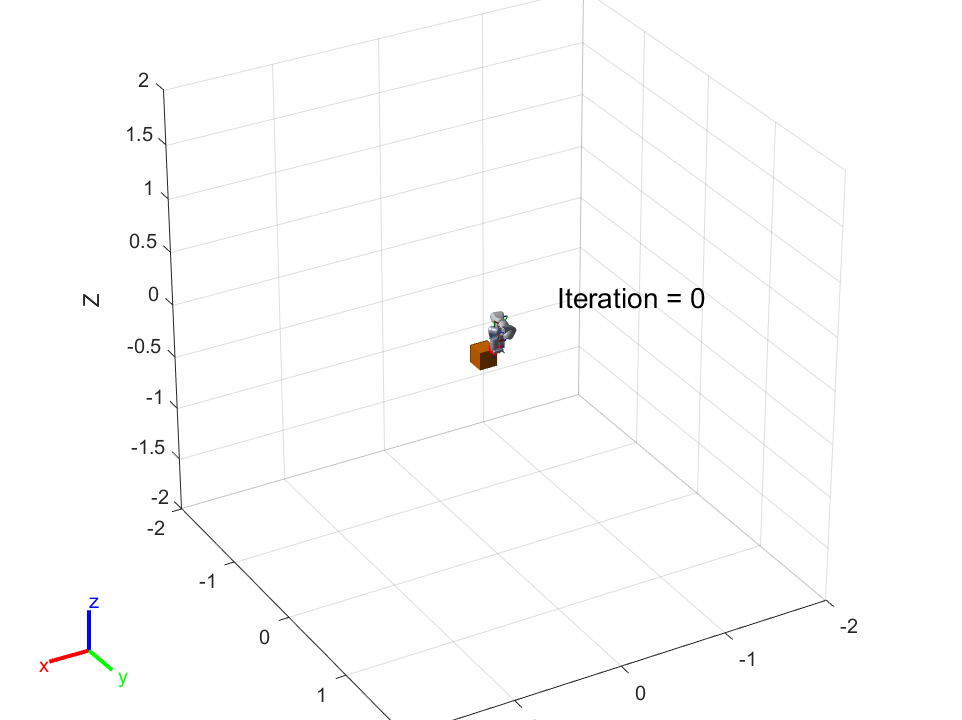

helperSTOMP;

[1K] M. alakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.